CASE = 0 % 0 is Step Reference Aggregated Power, 1 is Fluctuating Reference Aggregated Power

CASE = 0

MODE = 0 % 0 is using history communication topology and IACs parameters, 1 is using randomly generated topology and parameters

MODE = 0

% Generating topology
% different topology will result in different control effect
if(MODE==0)
    N=500; % the number of IACs
    L=zeros(N,N);
    eig2=0;
    while(eig2<0.001)
    L=zeros(N,N);    
    for i=1:N
        p=0;
        while(p<0.6)
            p=rand;
        end
        for j=i+1:N
            if(rand>p)
                L(i,j)=-1;
                L(j,i)=-1;
            end
        end
        L(i,i)=-sum(L(i,1:N));
    end
    eigen=eig(L);
    eig2=eigen(2);
    end
    L;
    eig(L);
    D=zeros(N,N);
    while(D==zeros(N,N))
    for i=1:N
        if(rand>0.85)
            D(i,i)=1;
        end
    end
    end
    sum(D,2);
end

% Setting the parameters of the IACs
% different parameters will result in different control effect
if(MODE==0)
    CT=1.9+0.2*rand(N,1); 
    RT=1.9+0.2*rand(N,1); 
    theta=2.3+0.4*rand(N,1);
    Tref=22+2*rand(N,1);
    dT=1.8+0.4*rand(N,1);
end
Ta=32;
A=diag(-1./(CT.*RT));
B=diag(-theta./(2*dT.*CT));
C=diag((Ta-Tref+dT)./(2*dT.*CT.*RT));


beta=0.2;
% kai=0.025;
% P_obj=2*N;
% rho0=0.72;
P0=5.6;

% Setting the parameters of the power system
df_t=zeros(1,200001);
dPti_t=zeros(1,200001);
u_P=0;
KP=-0.005;
KI=-0.01;
c_P=0;
c_I=0;
XP=zeros(4,1);   %df dPti dXgi dPgi 
TH=0.1;
TD=0.002;
TCA=4;
TCB=30;
TT=0.2;
TG=0.3;
RG=3.6;
AT=[-TD/2/TH,1/2/TH,0,0;
    0,-1/TT,1/TT,0;
    -TCA/TCB/TG/RG,0,-1/TCB,(TG-TCA)/TCB/TG;
    -1/RG/TG,0,0,-1/TG];
BT=[0;0;TCA/TCB/TG;1/TG];
H=[-1/2/TH;0;0;0];

% Initializing the state of IACs
x=0.3+0.5*rand(N,1);
v=zeros(N,1);
P_init=zeros(N,1);
u=zeros(N,1);
for i=1:N
    P_init(i)=0.25*P0+0.1*P0*rand;
end
P=P_init;
for i=1:N
    v(i)=A(i,i)*x(i)+B(i,i)*P(i)+C(i,i);
end


if(CASE==1)
    dPL=0.05*randn(1,200001);
    dPL(1:round(220/0.01)+1)=0;
end
P_t=zeros(1,200001);
Pobj_t=zeros(1,200001);
x_t=zeros(N,200001);
v_t=zeros(N,200001);
Pi_t=zeros(N,200001);
P_sum=sum(P);
dPTCLs=0;
drop=360;

% Frequency deviation with IACs participation 
for t=0:0.01:500
    n=round(t/0.01)+1;
    
    c_I=c_I+0.01*XP(1);
    c_P=XP(1);
    u_P=KP*c_P+KI*c_I;
    if(CASE==1)
        XP=XP+0.01*( AT*XP + BT*u_P + H*(0.8*dPL(n)+0.2*dPTCLs));
    elseif(CASE==0)
        XP=XP+0.01*( AT*XP + BT*u_P + H*(0.8*dPL+0.2*dPTCLs));
    end
    
    if(t<220) % Running to steady state for the ease of comparison
        kai=0.08;
        P_obj=900;
        P_nom=P_sum;
        if(CASE==0)
            dPL=0;
        end
    else 
        kai=0.025;
        P_obj=P_nom + drop * XP(1);
        dPTCLs=(P_sum-P_nom)/P_nom;
        if(CASE==0)
            dPL=0.03;  % percentage
        end
    end
    
        Pi=inv(B)*(v-A*x-C*ones(N,1));
        P_sum=P_sum + 0.01*sum(u);
        dP=P_obj-P_sum;
        u=beta*L*x+beta*L*v+kai*D*ones(N,1)*dP+kai*D*ones(N,1)*sign(dP);
        x=x+0.01*v;
        v=v+0.01*(A*v+B*u);

    
    Pi_t(1:end,n)=Pi;
    P_t(n)=P_sum;
    Pobj_t(n)=P_obj;
    x_t(1:N,n)=x;
    v_t(1:N,n)=v;
    df_t(n)=XP(1);

    if(mod(n,100)==0)
        n
    end
end 

n = 100

n = 200

n = 300

n = 400

n = 500

n = 600

n = 700

n = 800

n = 900

n = 1000

n = 1100

n = 1200

n = 1300

n = 1400

n = 1500

n = 1600

n = 1700

n = 1800

n = 1900

n = 2000

n = 2100

n = 2200

n = 2300

n = 2400

n = 2500

n = 2600

n = 2700

n = 2800

n = 2900

n = 3000

n = 3100

n = 3200

n = 3300

n = 3400

n = 3500

n = 3600

n = 3700

n = 3800

n = 3900

n = 4000

n = 4100

n = 4200

n = 4300

n = 4400

n = 4500

n = 4600

n = 4700

n = 4800

n = 4900

n = 5000

n = 5100

n = 5200

n = 5300

n = 5400

n = 5500

n = 5600

n = 5700

n = 5800

n = 5900

n = 6000

n = 6100

n = 6200

n = 6300

n = 6400

n = 6500

n = 6600

n = 6700

n = 6800

n = 6900

n = 7000

n = 7100

n = 7200

n = 7300

n = 7400

n = 7500

n = 7600

n = 7700

n = 7800

n = 7900

n = 8000

n = 8100

n = 8200

n = 8300

n = 8400

n = 8500

n = 8600

n = 8700

n = 8800

n = 8900

n = 9000

n = 9100

n = 9200

n = 9300

n = 9400

n = 9500

n = 9600

n = 9700

n = 9800

n = 9900

n = 10000

n = 10100

n = 10200

n = 10300

n = 10400

n = 10500

n = 10600

n = 10700

n = 10800

n = 10900

n = 11000

n = 11100

n = 11200

n = 11300

n = 11400

n = 11500

n = 11600

n = 11700

n = 11800

n = 11900

n = 12000

n = 12100

n = 12200

n = 12300

n = 12400

n = 12500

n = 12600

n = 12700

n = 12800

n = 12900

n = 13000

n = 13100

n = 13200

n = 13300

n = 13400

n = 13500

n = 13600

n = 13700

n = 13800

n = 13900

n = 14000

n = 14100

n = 14200

n = 14300

n = 14400

n = 14500

n = 14600

n = 14700

n = 14800

n = 14900

n = 15000

n = 15100

n = 15200

n = 15300

n = 15400

n = 15500

n = 15600

n = 15700

n = 15800

n = 15900

n = 16000

n = 16100

n = 16200

n = 16300

n = 16400

n = 16500

n = 16600

n = 16700

n = 16800

n = 16900

n = 17000

n = 17100

n = 17200

n = 17300

n = 17400

n = 17500

n = 17600

n = 17700

n = 17800

n = 17900

n = 18000

n = 18100

n = 18200

n = 18300

n = 18400

n = 18500

n = 18600

n = 18700

n = 18800

n = 18900

n = 19000

n = 19100

n = 19200

n = 19300

n = 19400

n = 19500

n = 19600

n = 19700

n = 19800

n = 19900

n = 20000

n = 20100

n = 20200

n = 20300

n = 20400

n = 20500

n = 20600

n = 20700

n = 20800

n = 20900

n = 21000

n = 21100

n = 21200

n = 21300

n = 21400

n = 21500

n = 21600

n = 21700

n = 21800

n = 21900

n = 22000

n = 22100

n = 22200

n = 22300

n = 22400

n = 22500

n = 22600

n = 22700

n = 22800

n = 22900

n = 23000

n = 23100

n = 23200

n = 23300

n = 23400

n = 23500

n = 23600

n = 23700

n = 23800

n = 23900

n = 24000

n = 24100

n = 24200

n = 24300

n = 24400

n = 24500

n = 24600

n = 24700

n = 24800

n = 24900

n = 25000

n = 25100

n = 25200

n = 25300

n = 25400

n = 25500

n = 25600

n = 25700

n = 25800

n = 25900

n = 26000

n = 26100

n = 26200

n = 26300

n = 26400

n = 26500

n = 26600

n = 26700

n = 26800

n = 26900

n = 27000

n = 27100

n = 27200

n = 27300

n = 27400

n = 27500

n = 27600

n = 27700

n = 27800

n = 27900

n = 28000

n = 28100

n = 28200

n = 28300

n = 28400

n = 28500

n = 28600

n = 28700

n = 28800

n = 28900

n = 29000

n = 29100

n = 29200

n = 29300

n = 29400

n = 29500

n = 29600

n = 29700

n = 29800

n = 29900

n = 30000

n = 30100

n = 30200

n = 30300

n = 30400

n = 30500

n = 30600

n = 30700

n = 30800

n = 30900

n = 31000

n = 31100

n = 31200

n = 31300

n = 31400

n = 31500

n = 31600

n = 31700

n = 31800

n = 31900

n = 32000

n = 32100

n = 32200

n = 32300

n = 32400

n = 32500

n = 32600

n = 32700

n = 32800

n = 32900

n = 33000

n = 33100

n = 33200

n = 33300

n = 33400

n = 33500

n = 33600

n = 33700

n = 33800

n = 33900

n = 34000

n = 34100

n = 34200

n = 34300

n = 34400

n = 34500

n = 34600

n = 34700

n = 34800

n = 34900

n = 35000

n = 35100

n = 35200

n = 35300

n = 35400

n = 35500

n = 35600

n = 35700

n = 35800

n = 35900

n = 36000

n = 36100

n = 36200

n = 36300

n = 36400

n = 36500

n = 36600

n = 36700

n = 36800

n = 36900

n = 37000

n = 37100

n = 37200

n = 37300

n = 37400

n = 37500

n = 37600

n = 37700

n = 37800

n = 37900

n = 38000

n = 38100

n = 38200

n = 38300

n = 38400

n = 38500

n = 38600

n = 38700

n = 38800

n = 38900

n = 39000

n = 39100

n = 39200

n = 39300

n = 39400

n = 39500

n = 39600

n = 39700

n = 39800

n = 39900

n = 40000

n = 40100

n = 40200

n = 40300

n = 40400

n = 40500

n = 40600

n = 40700

n = 40800

n = 40900

n = 41000

n = 41100

n = 41200

n = 41300

n = 41400

n = 41500

n = 41600

n = 41700

n = 41800

n = 41900

n = 42000

n = 42100

n = 42200

n = 42300

n = 42400

n = 42500

n = 42600

n = 42700

n = 42800

n = 42900

n = 43000

n = 43100

n = 43200

n = 43300

n = 43400

n = 43500

n = 43600

n = 43700

n = 43800

n = 43900

n = 44000

n = 44100

n = 44200

n = 44300

n = 44400

n = 44500

n = 44600

n = 44700

n = 44800

n = 44900

n = 45000

n = 45100

n = 45200

n = 45300

n = 45400

n = 45500

n = 45600

n = 45700

n = 45800

n = 45900

n = 46000

n = 46100

n = 46200

n = 46300

n = 46400

n = 46500

n = 46600

n = 46700

n = 46800

n = 46900

n = 47000

n = 47100

n = 47200

n = 47300

n = 47400

n = 47500

n = 47600

n = 47700

n = 47800

n = 47900

n = 48000

n = 48100

n = 48200

n = 48300

n = 48400

n = 48500

n = 48600

n = 48700

n = 48800

n = 48900

n = 49000

n = 49100

n = 49200

n = 49300

n = 49400

n = 49500

n = 49600

n = 49700

n = 49800

n = 49900

n = 50000

df_t1=zeros(1,200001)

df_t1 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


dPti_t=zeros(1,200001)

dPti_t =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


u_P=0;
KP=-0.005;
KI=-0.01;
c_P=0;
c_I=0;
XP=zeros(4,1)   %df dPti dXgi dPgi 

XP =      0
     0
     0
     0


% Frequency deviation without IACs participation 
for t=0:0.01:500
    if(t>220&&CASE==0)
        dPL=0.03;
    else
        dPL=0;
    end
    n=round(t/0.01)+1;
    c_I=c_I+0.01*XP(1);
    c_P=XP(1);
      u_P=KP*c_P+KI*c_I;
      if(CASE==1)
            XP=XP+0.01*( AT*XP + BT*u_P + H*0.8*dPL(n));
      else
          XP=XP+0.01*( AT*XP + BT*u_P + H*0.8*dPL);
      end
          
    df_t1(n)=XP(1);
    dPti_t(n)=XP(4);
end

t=0:0.01:500;

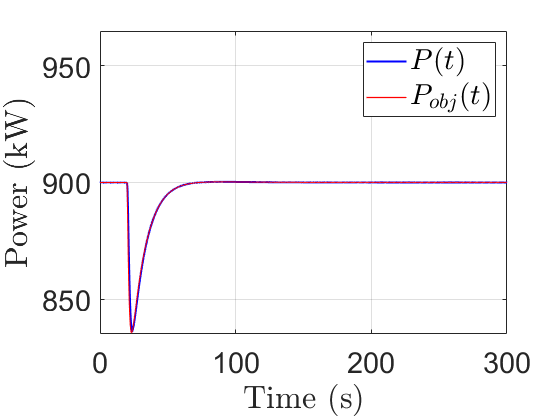

% Power curve 
figure(1)
clf
plot(t(20001:length(t))-200,P_t(20001:length(t)),"LineWidth",1.5,'Color','b')
hold on
plot(t(20001:length(t))-200,Pobj_t(20001:length(t)),"LineWidth",1,'Color','r')
grid on
% xlim([0.0 50.0])
ylim([835.0 965.0])
xlabel('Time (s)',"Interpreter","latex",'FontSize',25,"LineWidth",2)
ylabel('Power (kW)',"Interpreter","latex",'FontSize',25,"LineWidth",2)
legend({'$P(t)$','$P_{obj}(t)$'},"Interpreter","latex",'FontSize',22)
set(gca,'FontSize',22);

% axes('Position',[0.7,0.28,0.15,0.15]); % Generating subgraphs if necessary
% plot(t(20001:length(t))-200,P_t(20001:length(t)),"LineWidth",1.5,'Color','b')
% hold on
% plot(t(20001:length(t))-200,Pobj_t(20001:length(t)),"LineWidth",1,'Color','r')
% grid on
% set(gca,'FontSize',8);
% xlim([20,30]); 
% ylim([875,925]);

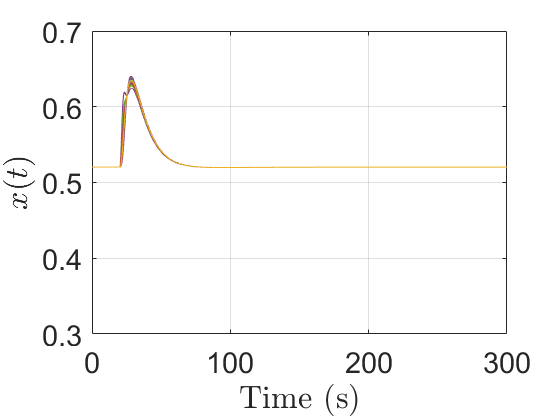

% Comfort state curve 
figure(2)
clf
for i=1:N
plot(t(20001:length(t))-200,x_t(i,20001:length(t)),"LineWidth",1)
hold on
grid on
end
ylim([0.3 0.7])
xlabel('Time (s)',"Interpreter","latex",'FontSize',25,"LineWidth",2)
ylabel('$x(t)$',"Interpreter","latex",'FontSize',25,"LineWidth",2)
set(gca,'FontSize',22);

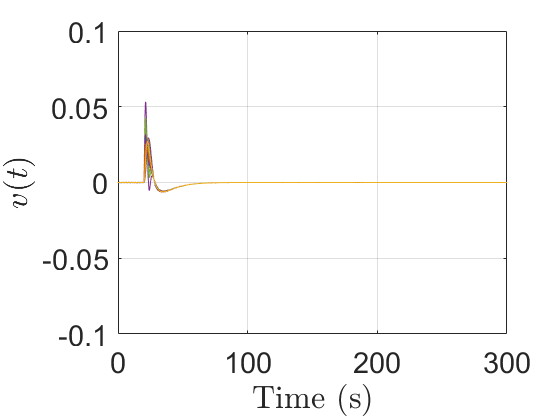

% v curve 
figure(3)
clf
for i=1:N
plot(t(20001:length(t))-200,v_t(i,20001:length(t)),"LineWidth",1)
hold on
grid on
end
ylim([-0.1 0.1])
xlabel('Time (s)',"Interpreter","latex",'FontSize',25,"LineWidth",2)
ylabel('$v(t)$',"Interpreter","latex",'FontSize',25,"LineWidth",2)
set(gca,'FontSize',22);

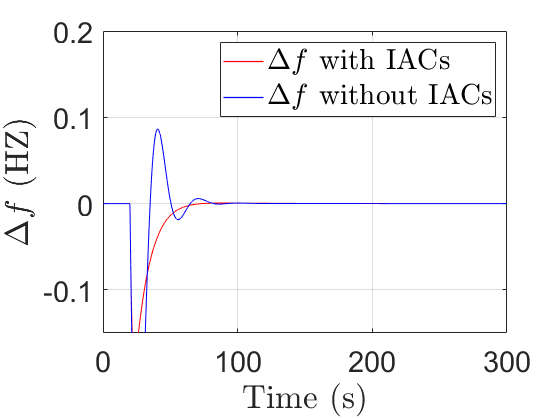

% frequency deviation curve 
figure(4)
clf
plot(t(20001:length(t))-200,df_t(20001:length(t)),"LineWidth",1,'Color','r')
hold on
plot(t(20001:length(t))-200,df_t1(20001:length(t)),"LineWidth",1,'Color','b')
grid on
ylim([-0.15 0.2])
set(gca,'FontSize',22);
xlabel('Time (s)',"Interpreter","latex",'FontSize',25,"LineWidth",2)
ylabel('$\Delta f$ (HZ)',"Interpreter","latex",'FontSize',25,"LineWidth",2)
legend({['$\Delta f$ with IACs'],['$\Delta f$ without IACs']},"Interpreter","latex",'FontSize',22)

T = clock; 
time=[num2str(T(1)),num2str(T(2)),num2str(T(3)),'_',num2str(T(4)),num2str(T(5)),'_primary','.mat'];
save(time)    